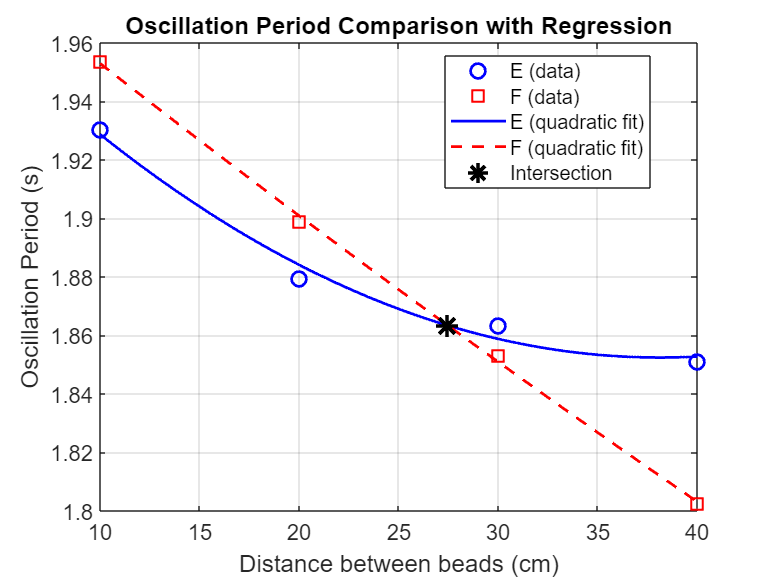

clc;
close all;
clear;

x = [10 20 30 40]; 
 
time_E = [193.03,187.94,186.35,185.12];
time_F = [195.37,189.88,185.30,180.24];  


T_E = time_E / 100;         
T_F = time_F / 100;           

p_E = polyfit(x, T_E, 2);     
p_F = polyfit(x, T_F, 2);     

x_fit = linspace(min(x), max(x), 1000); 
T_E_fit = polyval(p_E, x_fit);
T_F_fit = polyval(p_F, x_fit);

difference = T_E_fit - T_F_fit;
sign_changes = find(difference(1:end-1).*difference(2:end) <= 0);


if ~isempty(sign_changes)
    intersect_idx = sign_changes(1);
    x_intersect = interp1(difference(intersect_idx:intersect_idx+1),...
                        x_fit(intersect_idx:intersect_idx+1), 0);
    T_intersect = polyval(p_E, x_intersect);
else
    x_intersect = [];
    T_intersect = [];
    warning('No intersection found in the data range');
end

% Plotting
figure;
plot(x, T_E, 'bo', 'MarkerSize', 8, 'LineWidth', 1.5, 'DisplayName', 'E (data)');
hold on;
plot(x, T_F, 'rs', 'MarkerSize', 8, 'LineWidth', 1.5, 'DisplayName', 'F (data)');
plot(x_fit, T_E_fit, 'b-', 'LineWidth', 1.5, 'DisplayName', 'E (quadratic fit)');
plot(x_fit, T_F_fit, 'r--', 'LineWidth', 1.5, 'DisplayName', 'F (quadratic fit)');


if ~isempty(x_intersect)
    plot(x_intersect, T_intersect, 'k*', 'MarkerSize', 12,...
        'LineWidth', 2, 'DisplayName', 'Intersection');
end

xlabel('Distance between beads (cm)');
ylabel('Oscillation Period (s)');
title('Oscillation Period Comparison with Regression');
legend('Location', 'best');
grid on;
set(gca, 'FontSize', 12);
hold off;


if ~isempty(x_intersect)
    fprintf('Intersection at:\n');
    fprintf('X = %.2f cm\n', x_intersect);
    fprintf('T = %.3f s\n', T_intersect);
end

Intersection at:


X = 27.46 cm


T = 1.863 s


l=0.865

l = 0.8650

g_theory = ((2*pi)/T_intersect)^2*l

g_theory = 9.8349


erorr_theory = (g_theory- 9.81)/9.81 *100

erorr_theory = 0.2540

T=186.5/100;
g = ((2*pi)/T)^2*l

g = 9.8179


erorr = (g- 9.81)/9.81 *100

erorr = 0.0804